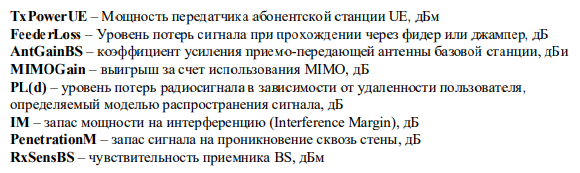

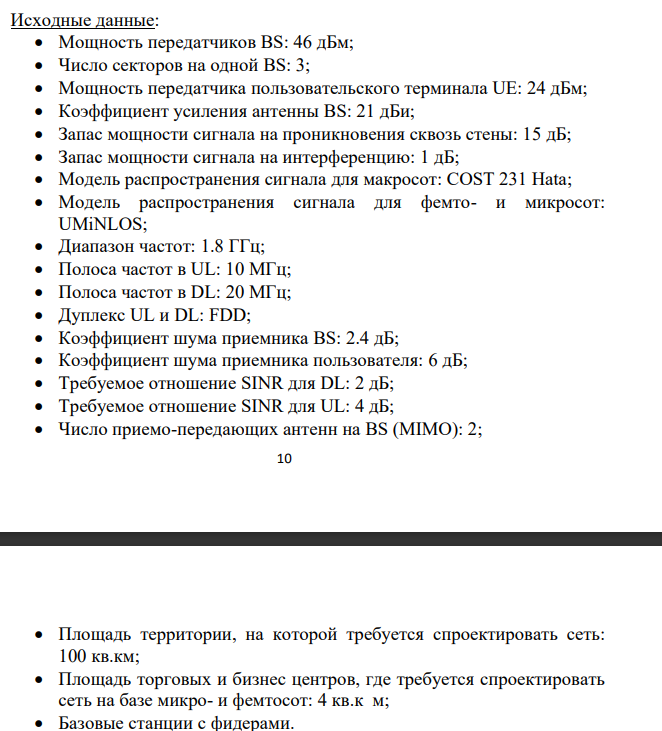

function z = MAPL_UL()
    TxPowerUE = 46; %дБм 
    FeederLoss = 2; %дБ
    AntGainBS = 21; %дБи
    MIMOGain = 3; %дБ
    IM = 1; %дБ
    PenetrationM = 15; %дБ
    NoiseFigure = 2.4; %дБ 
    ThermalNoise = -174 + 10 * log10(10 * 10^6); %дБ
    ReqiredSINR = 4; %дБ
    RxSens = NoiseFigure + ThermalNoise + ReqiredSINR;
    z = TxPowerUE - FeederLoss + AntGainBS + MIMOGain - RxSens - IM - PenetrationM;
end